rosshutdown

Shutting down global node /matlab_global_node_04629 with NodeURI http://192.168.1.100:63294/


setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311','NodeHost','192.168.1.100');

Initializing global node /matlab_global_node_30786 with NodeURI http://192.168.1.100:63333/


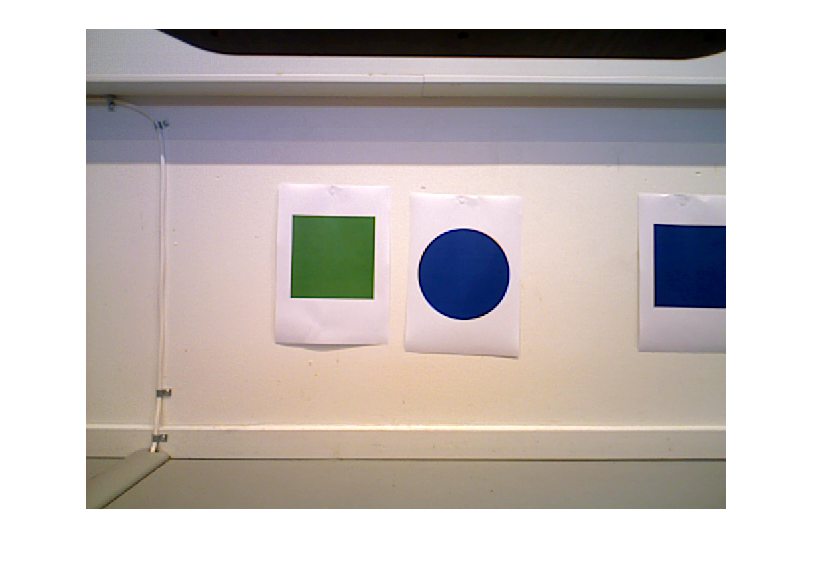


% Grap image from camera
if ismember('/camera/rgb/image_color/compressed',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_color/compressed');
end

if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

% Read scan continously
if ismember('/camera/depth_registered/points',rostopic('list'))
    pointcloudsub = rossubscriber('/camera/depth_registered/points');
    figure
    while(1)
        pc = receive(pointcloudsub); %Receive message
        scatter3(pc);
    end
    
end

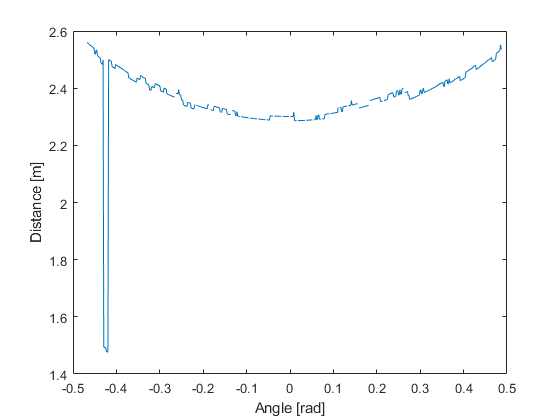

% Read scan continously
if ismember('/scan',rostopic('list'))
    scansub = rossubscriber('/scan');
    
    figure
    while(1)
        linescan = receive(scansub); %Receive message
        ranges = linescan.Ranges; % Extract scan
        angles = linescan.AngleMin:linescan.AngleIncrement:linescan.AngleMax;
        plot(angles, ranges)
        xlabel('Angle [rad]')
        ylabel('Distance [m]')
        %saveas(gcf,'linescan.png')
    end
end